# CMCN Exercise 5

#### Vic-Fabienne Schumann 811165

## Task 1

e_coli_model = readCbModel('data/e_coli_core.xml')

e_coli_model = struct with fields:
                                S: [72×95 double]
                             mets: {72×1 cell}
                                b: [72×1 double]
                           csense: [72×1 char]
                             rxns: {95×1 cell}
                               lb: [95×1 double]
                               ub: [95×1 double]
                                c: [95×1 double]
                        osenseStr: 'max'
                            genes: {137×1 cell}
                            rules: {95×1 cell}
                        geneNames: {137×1 cell}
                        compNames: {2×1 cell}
                            comps: {2×1 cell}
                         proteins: {137×1 cell}
                       metCharges: [72×1 double]
                      metFormulas: {72×1 cell}
                         metNames: {72×1 cell}
                        metHMDBID: {72×1 cell}
                        metKEGGID: {72×1 cell}
                 

indx_biomass_reaction = find( not ( cellfun( "isempty", strfind(e_coli_model.rxns, 'BIOMASS'))))

indx_biomass_reaction = 25

% objective to maximize biomass flux
biomass_max_model = changeObjective(e_coli_model, 'BIOMASS_Ecoli_core_w_GAM', 1000)

biomass_max_model = struct with fields:
                                S: [72×95 double]
                             mets: {72×1 cell}
                                b: [72×1 double]
                           csense: [72×1 char]
                             rxns: {95×1 cell}
                               lb: [95×1 double]
                               ub: [95×1 double]
                                c: [95×1 double]
                        osenseStr: 'max'
                            genes: {137×1 cell}
                            rules: {95×1 cell}
                        geneNames: {137×1 cell}
                        compNames: {2×1 cell}
                            comps: {2×1 cell}
                         proteins: {137×1 cell}
                       metCharges: [72×1 double]
                      metFormulas: {72×1 cell}
                         metNames: {72×1 cell}
                        metHMDBID: {72×1 cell}
                        metKEGGID: {72×1 cell}
            

% switch solver
changeCobraSolver('glpk');

 > isCompatible: glpk is compatible and fully tested with MATLAB R2020b on your type of operating system.


% run FBA

fba_model = optimizeCbModel(biomass_max_model);

% alternative way
% using linprog an linear models

f = (1:95)

f =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


f(1:95) = 0

f =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


f(indx_biomass_reaction) = -1

f =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


f = transpose(f)

f =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


A = []


A =

     []



b = []


b =

     []



Aeq = e_coli_model.S

Aeq =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.2557         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

beq = (1:72)

beq =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


beq(1:72) = 0

beq =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


beq = transpose(beq)

beq =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


lb = e_coli_model.lb

lb = 	1.0e+03 *

         0
         0
   -1.0000
   -1.0000
         0
   -1.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000


ub = e_coli_model.ub

ub =         1000
        1000
        1000
        1000
        1000
        1000
        1000
        1000
        1000
        1000



[x, fval] = linprog (f, A, b, Aeq, beq, lb, ub)

Optimal solution found.



x = 	1.0e+03 *

    0.0075
         0
    0.0049
   -0.0160
    0.0050
         0
         0
   -0.0147
    0.0032
         0


fval = -0.8739

The optimal solution is with -0.87

## Task 2

written with help of Ilia & Stephan

knockout_reactions = reactionKnockouts(biomass_max_model, fba_model)

knockout_reactions =     0.8056
    1.0000
    0.9877
    0.0000
    0.9884
    1.0000
    1.0000
    0.0000
   -0.0000
    1.0000


knockout_reactions

## Task 3

knockout_reactions =     0.8056
    1.0000
    0.9877
    0.0000
    0.9884
    1.0000
    1.0000
    0.0000
   -0.0000
    1.0000


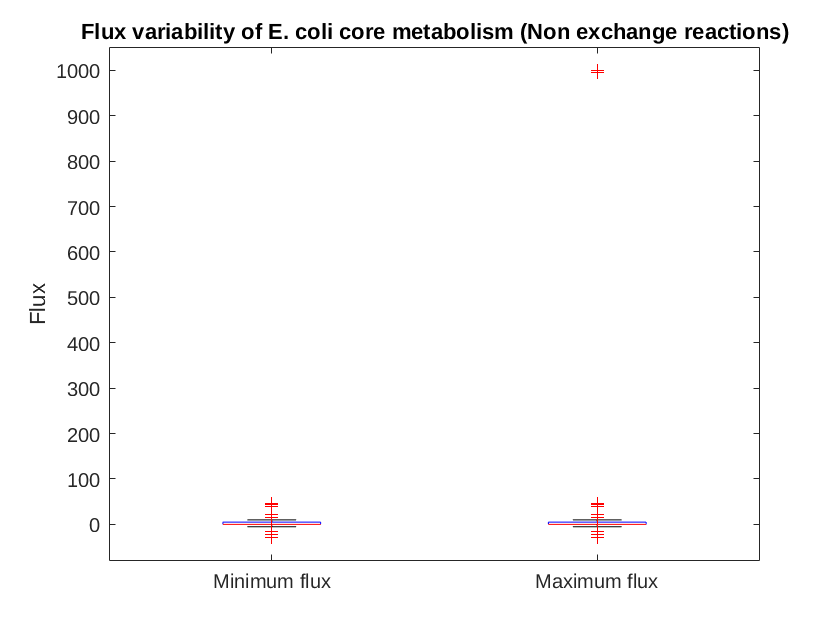

% reset all objectives back to 0
e_coli_model_reset = changeObjective(e_coli_model , e_coli_model.rxns(indx_biomass_reaction), 1);

% run flux balance analysis
[min_flux, max_flux] = fluxVariability(e_coli_model_reset);
fluxvar = [min_flux max_flux];

% get grouping vector
group_vec = contains(e_coli_model_reset.rxnNames, 'exchange');

fluxvar_exch = fluxvar(group_vec,:);
fluxvar_nex = fluxvar(~group_vec,:);

% plot the non exchange variability as a boxplot
boxplot(fluxvar_nex, 'labels', {'Minimum flux' 'Maximum flux'})
title('Flux variability of E. coli core metabolism (Non exchange reactions)')
ylabel('Flux')

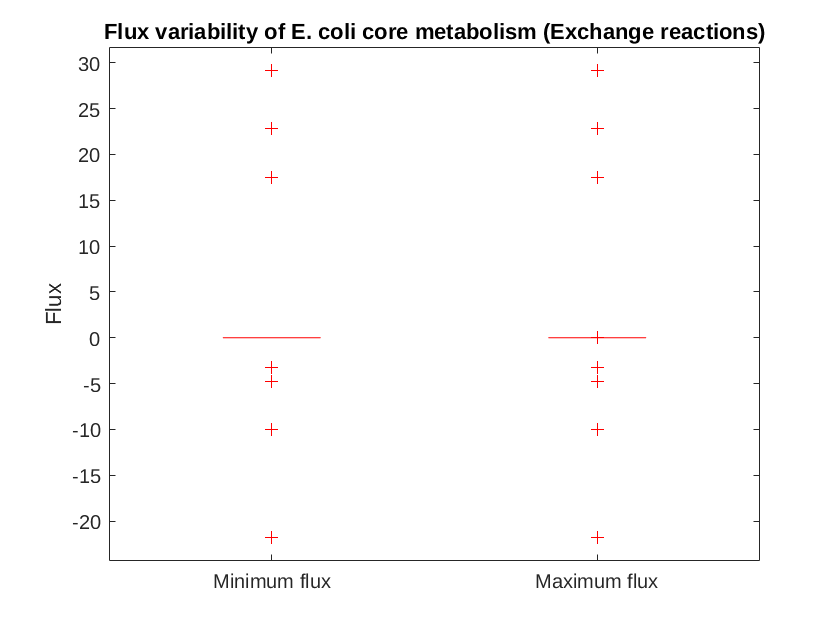

% plot the non exchange variability as a boxplot
boxplot(fluxvar_exch, 'labels', {'Minimum flux' 'Maximum flux'})
title('Flux variability of E. coli core metabolism (Exchange reactions)')
ylabel('Flux')

To achieve the same goal without the convenience of the fluxVariability() function, we need to manually loop through all the reaction and calculate their minimum and maximum flux.

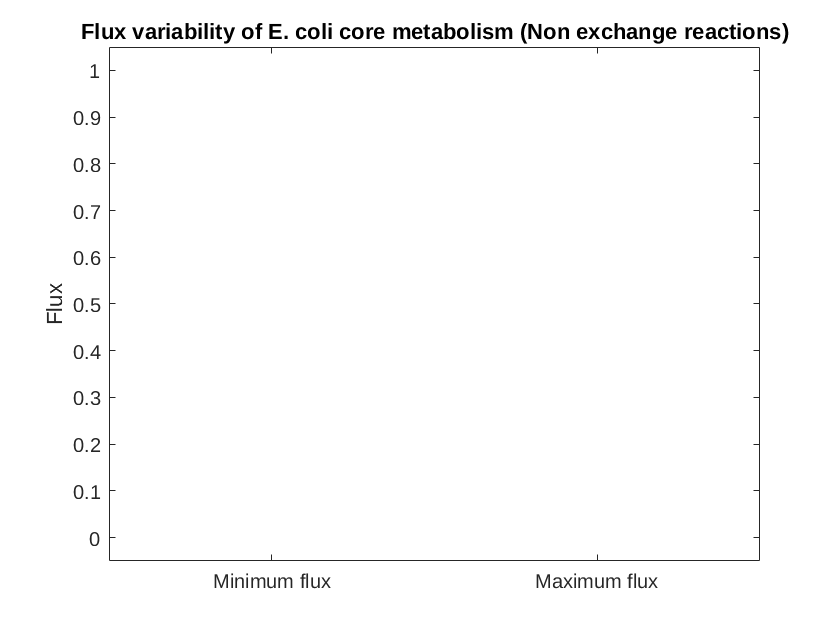

% initialise storage arrays
min_flux_man = zeros(length(e_coli_model_reset.rxns), 1);
max_flux_man = zeros(length(e_coli_model_reset.rxns), 1);

e_coli_model_temp = changeRxnBounds(e_coli_model_reset, e_coli_model_reset.rxns(indx_biomass_reaction), fba_model.f);

% loop though the reaction indices
for rxn_idx = 1:size(e_coli_model_reset.rxns, 1)
       
   e_coli_model_temp = changeObjective(e_coli_model_temp, e_coli_model_reset.rxns(rxn_idx));
   
   % calculate the minimum and optimum flux
   min_flux_man(rxn_idx) = optimizeCbModel(e_coli_model_temp, 'min').f;
   max_flux_man(rxn_idx) = optimizeCbModel(e_coli_model_temp, 'max').f;
        
end

fluxvar_man = [min_flux_man max_flux_man];

fluxvar_man_exch = fluxvar_man(group_vec,:);
fluxvar_man_nex = fluxvar_man(~group_vec,:);

% plot the non exchange variability as a boxplot
boxplot(fluxvar_man_nex, 'labels', {'Minimum flux' 'Maximum flux'})
title('Flux variability of E. coli core metabolism (Non exchange reactions)')
ylabel('Flux')

The output is empty. I don't know what the mistake is here. 